# Homework 4

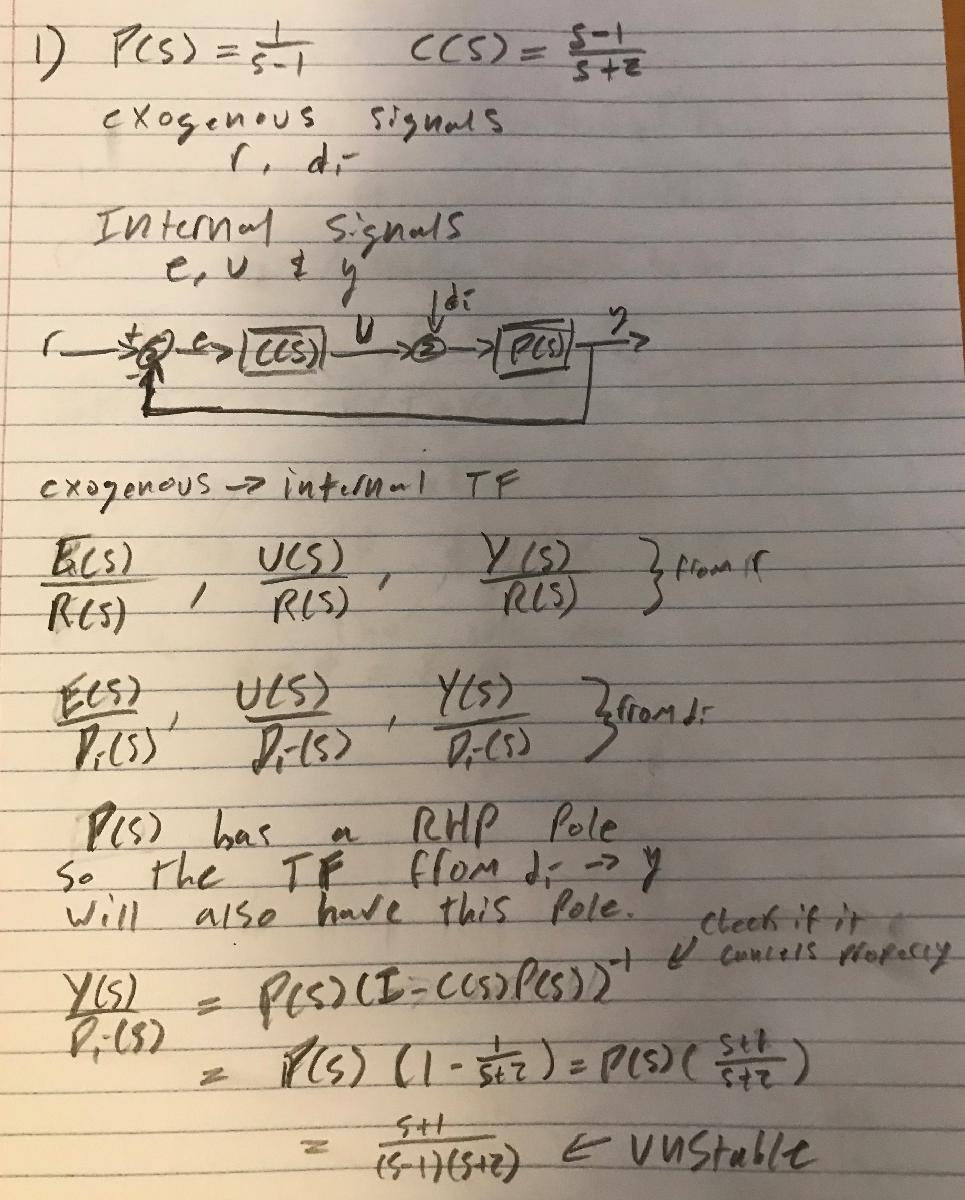

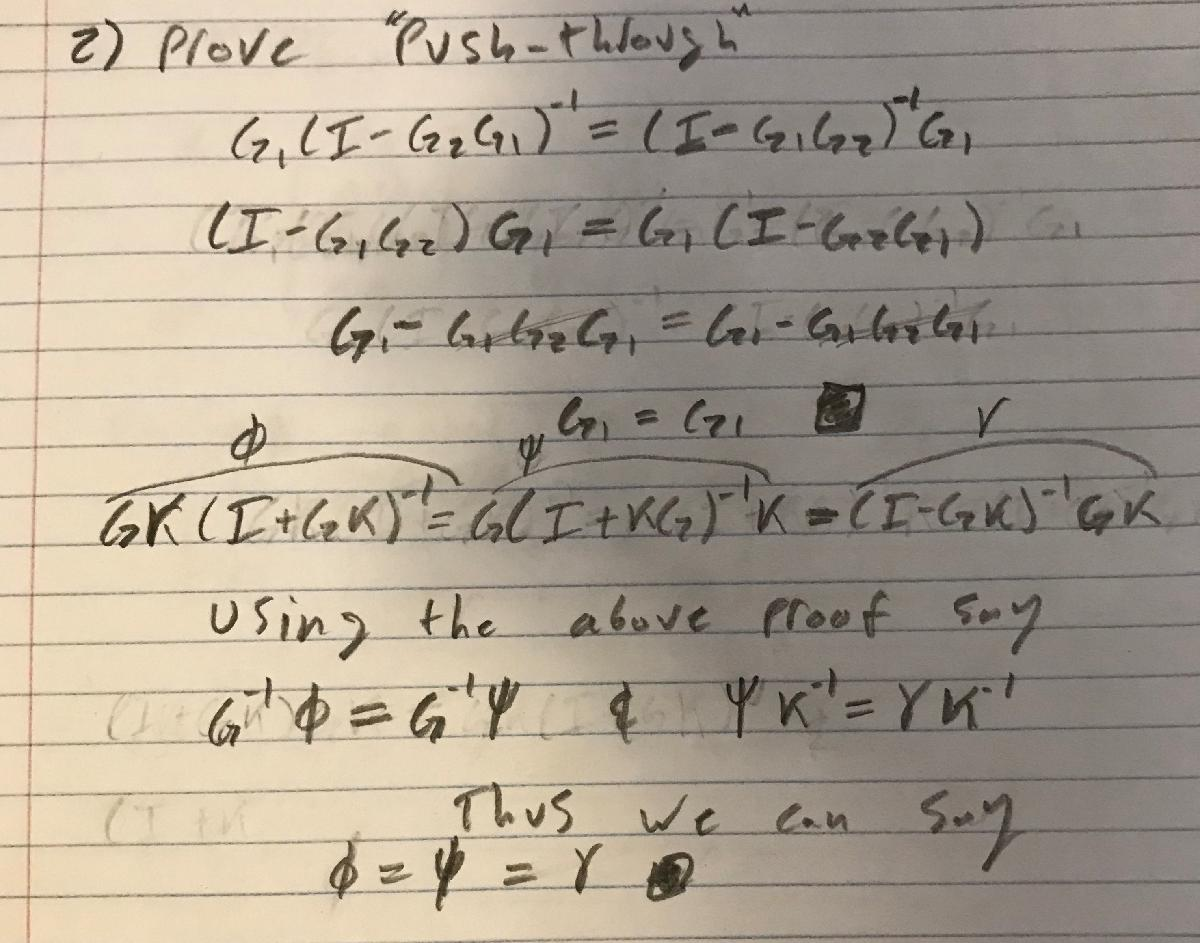


% F4-Phantom Dynamics
A = [-0.8	-0.0006		-12		0;
	   0     -0.014   -16.64  -32.2;
	   1    -0.0001    -1.5     0;
	   1       0         0      0];

B = [ -19  -2.5
     -0.66 -0.5
     -0.16 -0.6
       0     0];

C = [1 0 0 0;
	 0 0 1 0];

D = [0 0;
	0 0];

f4_ss = ss(A, B, C, D)

f4_ss =
 
  A = 
            x1       x2       x3       x4
   x1     -0.8  -0.0006      -12        0
   x2        0   -0.014   -16.64    -32.2
   x3        1  -0.0001     -1.5        0
   x4        1        0        0        0
 
  B = 
          u1     u2
   x1    -19   -2.5
   x2  -0.66   -0.5
   x3  -0.16   -0.6
   x4      0      0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



#### a) Generate a MATLAB plot that contains the singular value bode plots in red combined with the bode magnitude plots of the 4 individual transfer functions from the 2 inputs to 2 outputs. Does the maximum singular value plot envelope the individual transfer function plots?

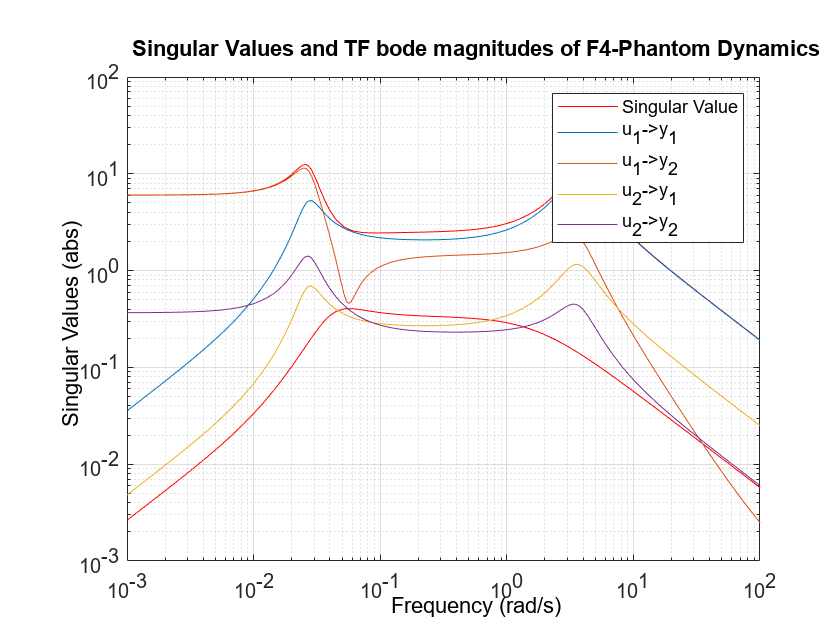

figure
hold on
sigma(f4_ss, 'r');
for i = 1:size(f4_ss, 1)
	[num, den] = ss2tf(A, B, C, D, i);
	for j = num'
		sys = tf(j', den);
		[magnitude, ~, frequencies] = bode(sys);
		semilogx(frequencies, squeeze(magnitude));

	end
end
title("Singular Values and TF bode magnitudes of F4-Phantom Dynamics")
legend("Singular Value", "u_1->y_1", "u_1->y_2", "u_2->y_1", "u_2->y_2")

The singular values almost entirely envolope the bode magnitudes. The only exception is at around 0.4 rad/s there is a dip in two of the TFs that causes the magnitude to drop below the singlular value evelope. This is because our transfer functions are decoupled from the each other when we call ss2tf(). 

#### b) From the plot in (a), estimate the worst case output 2-norm (in absolute units, not dB) for any $L_2^2[0, \infty )$ input signal with 2-norm equal to 1.

Probably greater than 12

#### c) For the frequency ω = 10 rad/s, what input direction is amplified most? (the MATLAB command `evalfr` is useful here)

u1 -> y1, clearly the highest at 10 rad/s on the plot above. Also the matrix returned by evalfr clearly has the largest element at (1,1)

abs(evalfr(f4_ss, 10i))

ans =     2.1365    0.2810
    0.2137    0.0746


#### 4. In this problem you will design a feedback control for the thrust vector actuator for the RL10-B2 liquid rocket engine which is on the second stage of the Delta IV launch vehicle. The gimbal actuator takes an input voltage v(t) and rotates the nozzle an angle φ(t), whose dynamics are described by

P (s) = φ(s) / v(s) = 40(s + 1)/(s^2 + s + 4)(s + 6)

The desired closed loop system should have decent tracking behavior so that it can follow the reference command from the rocket’s guidance system. The system has a closed loop bandwidth constraint due to the large inertia of the nozzle and the limits of the gimbal actuator to rotate it. Assume the following specifications for your initial controller design:

	- Maximum closed loop bandwidth of 2 Hz (12.56 rad/s)

	- Tracking error of less than 10% from 0 to 0.5 Hz (3.14 rad/s)

	- Closed loop step response with a maximum overshoot of 20%

P = tf([40 40], [1 7 10 24])

P =
 
         40 s + 40
  -----------------------
  s^3 + 7 s^2 + 10 s + 24
 
Continuous-time transfer function.



#### (a) Convert the closed loop performance requirements above into open loop constraints. Design a dynamic compensator C(s) and generate a bode plot of L(s) = P (s)C(s) that includes all the constraints so that you can visually verify that your design meets all performance requirements.

The maximum bandwidth requirement can be satisfied by keeping $|PC| < 0.707$ for frequencies greater than the band width 2 Hz

The constraint on tracking performance can be satisfied by keeping $|PC|> 10$ for frequencies (0, 0.5) Hz.

The constraint on overshoot can be satisfied by a phase margin of > 45.6.

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



K = 3;
td = 1 / 20;
ti = 1 / 2;
C_pid = K / s * (((td * s) + 1) * (s + (1 / ti)))

C_pid =
 
  0.15 s^2 + 3.3 s + 6
  --------------------
           s
 
Continuous-time transfer function.



System GM Inf, PM 47.555850

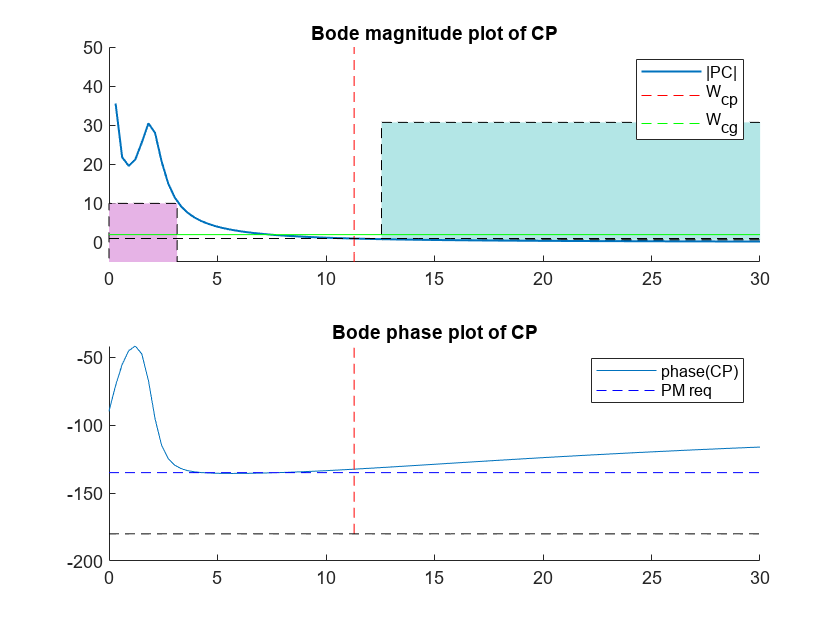


fr_reqs(P * C_pid)

#### b) Generate a closed loop step response and error signal e(t) for a reference input of r =

#### sin (2πωt) for ω = 0.5 Hz to show that specs have been met.

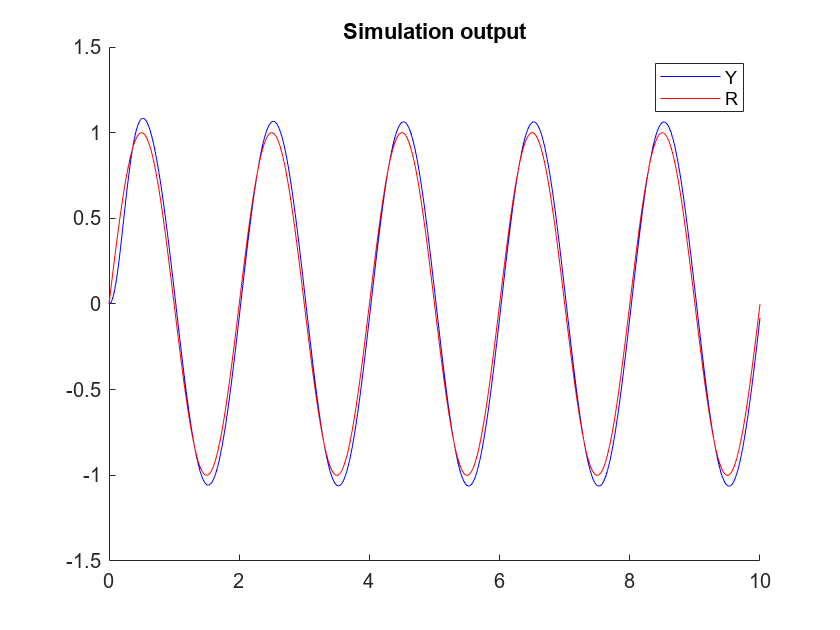

tmax = 10;
tsteps = 1000;
t_space = linspace(0, tmax, tsteps);
r = sin(pi * t_space);

y = lsim(feedback(P * C_pid, 1), r, t_space);
figure
hold on
plot(t_space, y, 'b')
plot(t_space, r, 'r')
title("Simulation output")
legend("Y", "R")

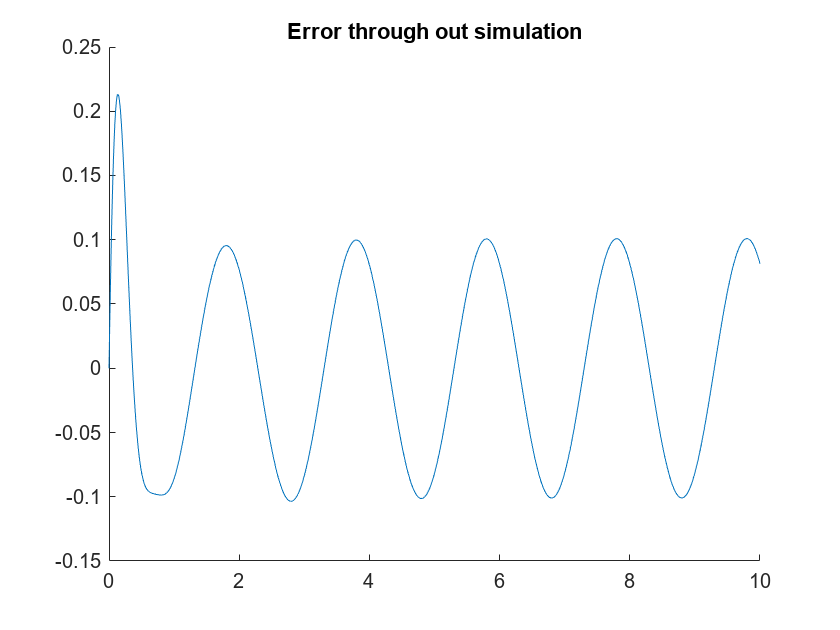


figure
hold on
plot(t_space, r - y')
title("Error through out simulation")

After initial flight testing, it is determined that there are disturbances that effect the behavior

of this system. Specifically, vibrations from the engine (high frequency) and fuel slosh (low

frequency) were shown to have a significant impact. You are now to redesign your controller

assuming that disturbances can arise from a large frequency range. Assume disturbances d(t)

that enter the loop at the plant input can be any signal with finite energy d(t) ∈ L2[0, ∞),

and redesign your controller to minimize the effect on the output φ(t), which is also assumed

to be a finite energy signal:

- Maximum ‖φ‖2/‖d‖2 gain should be less than 1/3 (3X reduction)

#### (c) Re-generate the open loop bode plot of L(s) = P (s)C(s) with your new compensator

#### that includes all the constraints so that you can visually verify that your design meets

#### all the original performance requirements listed in the first part of the question.

by solving the equation S = 1/ (1 + L) at the system bandwidth with the requirment S < 0.3.

(1+L) > 3 => L > 2

% K = 10;
% td = 1 / 7;
% ti = 1 / 1;
% C_pid = K / (s + 15) * (((td * s) + 1) * (s + (1 / ti)))

K = 7.5;

a1 = 1;
omega_d = 2;

a2 = 0.1;
omega_g = 10;

C_lead = tf([1 omega_d], [a1 omega_d]);
C_lag = tf([1 omega_g], [1 omega_g / a2]);

C_lead_lag = K * (C_lead + C_lag)

C_lead_lag =
 
  15 s^2 + 855 s + 1650
  ---------------------
    s^2 + 102 s + 200
 
Continuous-time transfer function.



L = P * C_lead_lag

L =
 
        600 s^3 + 34800 s^2 + 100200 s + 66000
  --------------------------------------------------
  s^5 + 109 s^4 + 924 s^3 + 2444 s^2 + 4448 s + 4800
 
Continuous-time transfer function.



System GM Inf, PM 26.320989

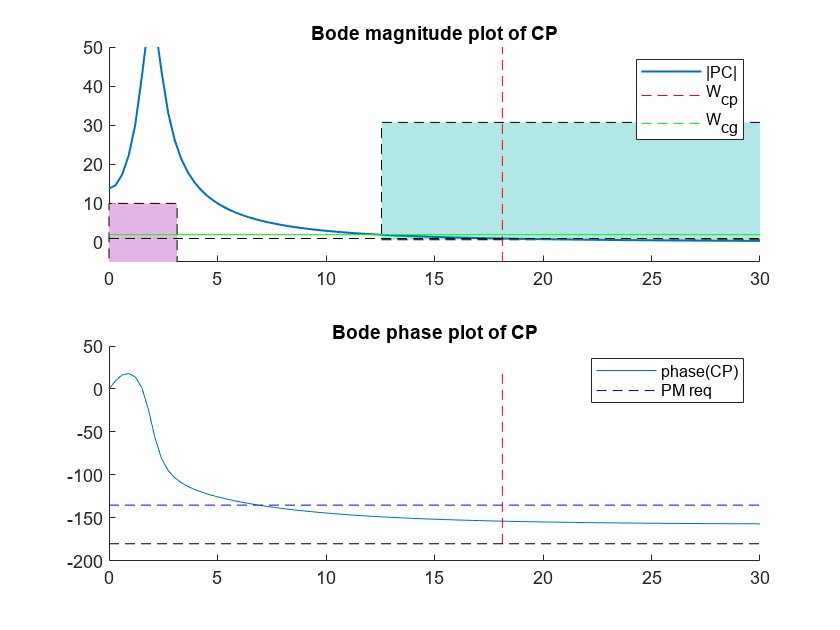

fr_reqs(L)

#### (d) Generate a plot of the magnitude of the transfer function P S(s) in absolute units to

#### estimate the maximum ‖φ‖2/‖d‖2 gain and visually verify that you also satisfy this

#### requirement (you can check this with `norm(`P S`, inf)`), along with a step and impulse

#### response of P S(s) to visualize the effect of the disturbance on your system.

S = 1 / (1 + L)

S =
 
    s^5 + 109 s^4 + 924 s^3 + 2444 s^2 + 4448 s + 4800
  -------------------------------------------------------
  s^5 + 109 s^4 + 1524 s^3 + 37244 s^2 + 104648 s + 70800
 
Continuous-time transfer function.



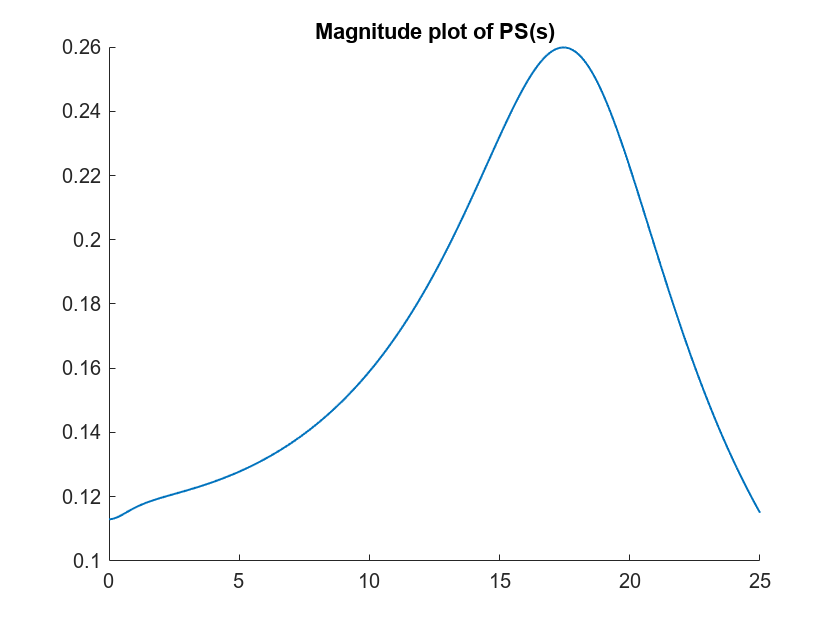

freq = linspace(0, 25, 1000);
[mag, phase, freq] = bode(P * S, freq);

figure
hold on
semilogx(freq, squeeze(mag), 'LineWidth', 1)
title("Magnitude plot of PS(s)")

norm(P*S, 'inf')

ans = 0.2599

function fr_reqs(sys)
	x_range = [0 30];
	y_range = [-5 50];
	x_lin = linspace(x_range(1), x_range(2));
	y_lin = linspace(y_range(1), y_range(2));

	[mag, phase, freq] = bode(sys, x_lin);
	[Gm,Pm,Wcg,Wcp] = margin(mag, phase, freq);

	fprintf("System GM %f, PM %f", Gm, Pm);

	figure
	subplot(2,1,1)
	hold on
	rectangle('Position', [0 -10 3.14 20], 'LineStyle', '--', 'FaceColor',[.9 .7 .9])
	rectangle('Position', [12.56 0.707 30 30], 'LineStyle', '--', 'FaceColor',[.7 .9 .9])
	semilogx(freq, squeeze(mag), 'LineWidth', 1)
	plot(Wcp * ones(size(x_lin)), y_lin, 'r--')
	plot(Wcg * ones(size(x_lin)), y_lin, 'g--')
	plot(x_lin, 2 * ones(size(x_lin)), 'g')
	plot(x_lin, ones(size(x_lin)), '--', 'color', 'black')
	xlim(x_range)
	ylim(y_range)
	title("Bode magnitude plot of CP")
	legend("|PC|", "W_{cp}", "W_{cg}")
	
	subplot(2, 1, 2)
	hold on
	min_ang = min(min(phase), -180);
	plot(freq, squeeze(phase))
	plot(x_lin, (-180 + 45) * ones(size(x_lin)), 'b--')
	plot(Wcp * ones(size(x_lin)), linspace(min_ang, max(phase)), 'r--')
	plot(Wcg * ones(size(x_lin)), linspace(min_ang, max(phase)), 'g--')
	plot(x_lin, -180 * ones(size(x_lin)), '--', 'color', 'black')
	legend("phase(CP)", "PM req")
	xlim(x_range)
	title("Bode phase plot of CP")
end